#   ECSE 343: Numerical Methods in Engineering

#  Assignment 4

Due Date: 9th April 2021

Student Name: Hongtao Xu

Student ID:   260773785 

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with the **PDF** copy of this file.

Note: You can write the function in the appendix section using the provided stencils.

Question 1: **Nonlinear Equations for univariate case.**

a) Bisection Method is used for tfinding the roots of a continuous function, $f\left(x\right)$, given endpoints;$a,b$ with $f\left(a\right)\ldotp f\left(b\right)<0$ . The interval $\left\lbrack a\;\;b\right\rbrack$contains a root, $x_r$, because $f\left(a\right)$ and $f\left(b\right)$ have opposite signs.

Bisection method bisects the given interval at the midpoint, $c=\frac{a+b}{2}$ and then chooses a new interval based such that end of point of interval have opposite signs, i.e., if $f\left(a\right)\ldotp f\left(c\right)<0$, then the new interval is set to $\left\lbrack a\;\;c\right\rbrack$, else if $f\left(c\right)\ldotp f\left(b\right)<0$ then the interval is set to $\left\lbrack c\;\;b\right\rbrack$.

The above procedure is repeated until the following two conditions are simultaneously met, 

- The function value at the interval is sufficiently small, i.e., ${\left\|f\left(c\right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The new interval is sufficiently small, i.e., ${\left\|a-b\right\|}_2 <\epsilon_{\textrm{tolerance}}$

Implement the Bisection Method in the cell below to find the root of $f\left(x\right)=x^4 -{\textrm{􀀀2}\;x}^2 -4$ in the interval $\left\lbrack -3\;\;\;3\right\rbrack \;$using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$. **Show the number of iterations the bisection method took to converge.**

Use the cell below to implement your code. 

Note: There is no need to write the function for Bisection Method. However, if you wish to implement the function, use the appendix.

f1 = -1;
f2 = 1;
t = 1;
s = 1;
b= -3;
a = 3;
c = 3;
tol = 1e-5;
while t >= tol & s >=tol
if f1*f2 < 0
a = c;
else
b = c;
end
c = (b+a)/2;
f1 = b^4-2*b^2-4;
f2 = c^4-2*c^2-4;
fb = a^4-2*a^2-4;
s = norm(b-a); 
t = norm(f2/2);   
end
result = c

result = -1.7989

% the number of iterations the bisecton method took to converge is here

b) ** Newton-Raphson**

 Bisection Method requires the given function,$f\left(x\right)$ to be continuous, Newton-Raphson requires $f\left(x\right)$ to be continuous and differentiable. While the Newton- Raphson method converges faster than the bisection method, however, Newton-Raphson method does not guarantee convergence. Newton-Raphson works by linearising the $f\left(x\right)$, at the given initial guess, $x^{\left(0\right)}$as shown below


$$f\left(x\right)=f\left(x^{\left(0\right)} \right)+{f\left(x^{\left(0\right)} \right)}^{\prime } \left(x-x^{\left(0\right)} \right)$$


Setting the expression on the right to zero, provides an approximation to the root, and we obtain


$$x^{\left(1\right)} =x^{\left(0\right)} -\frac{f\left(x^{\left(0\right)} \right)}{{f\left(x^{\left(0\right)} \right)}^{\prime } }$$


Then, the function,$\;f\left(x\right)$, is again linearised using approximation,$x^{\left(1\right)}$as the initial guess, to obtain new approximation of the root. After $k$ iterations the new approximation for the root becomes,

  
$$x^{\left(k+1\right)} =x^{\left(k\right)} -\frac{f\left(x^{\left(k\right)} \right)}{{f\left(x^{\left(k\right)} \right)}^{\prime } }$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|f\left(x^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

Implement the **Newton-Raphson** Method in the cell below to find the root of $f\left(x\right)=x^4 -{\textrm{􀀀2}\;x}^2 -4$ use intial guess of $x^{\left(0\right)} =3$ using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$.  If the convergence is not reached in 100 iterations, quit the algorithm by displaying an error message indicating that Newton-Raphson failed to converge. 

Show the number of iterations the Newton-Raphson method took to converge. 

Also plot the 2-Norm of difference between consecutive solutions ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2$ for each iteration. 

x0 = 3;
x1 = x0;
f1 = x1^4-2*x1^2-4;
fx = zeros(2,100);
tol = 1e-5;
ts = 1;
x = 0;
t = 1;
while t >= tol && ts >=tol
fx(1,x+1) = x;
df = 4*x1^3-4*x1;
x1 = x1-f1/df;
f1 = x1^4-2*x1^2-4;
ts = norm(x1-x0);
t = norm(f1);
fx(2,x+1) = ts;
if x == 100
ts = 1e-6;
t = 1e-6;
fprintf("Iteration over 101 times, Newton-Raphson can't converge")
end
x = x+1;
x0 = x1;
end
if x < 100
numberofit = x-1
finalx = x0
end

numberofit = 5

finalx = 1.7989

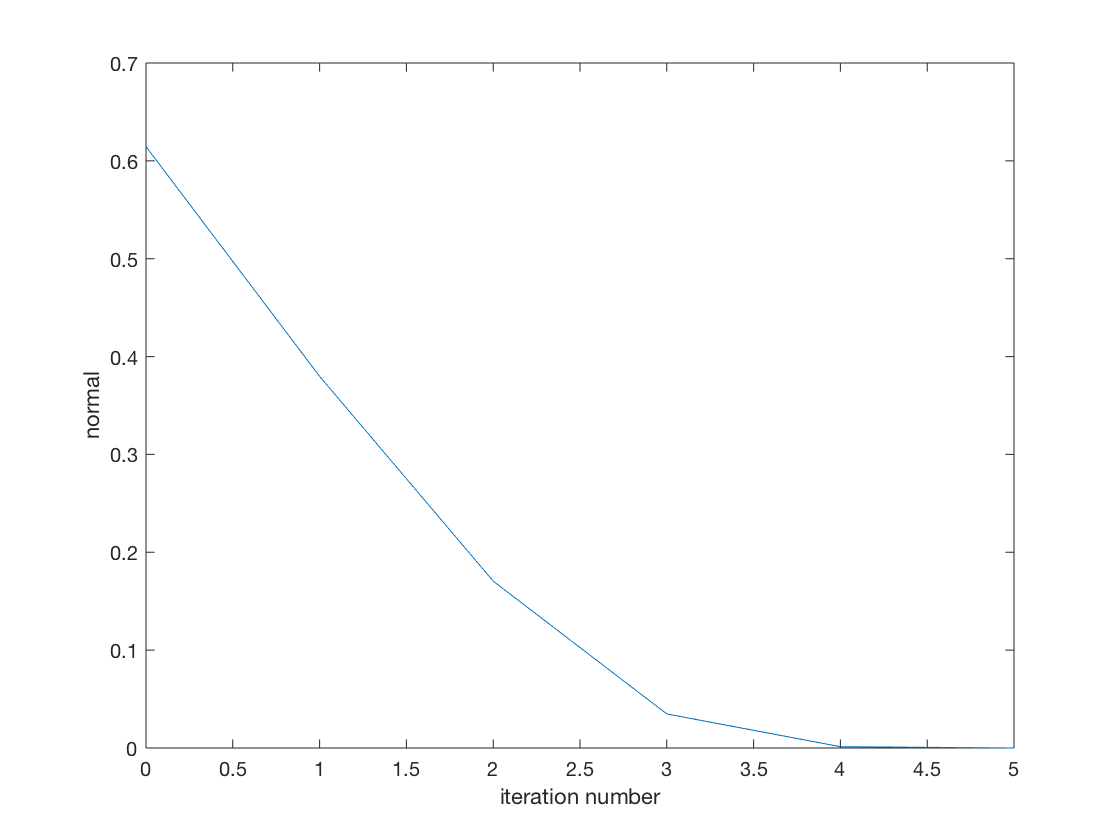

% the number of iterations the Newton-Raphson method took to converge is here
plot(fx(1,1:x),fx(2,1:x))
ylabel('normal')
xlabel('iteration number')

c) In this part implement the **Bisection Method**, and the** Newton-Raphson Method** to find the roots of $f\left(x\right)\;=\;\arctan \left(x\right)$. Use  $\epsilon_{\textrm{tolerance}} ={10}^{-5}$, to stop the algorithms. For bisection method use the interval $\left\lbrack -4\;\;4\;\right\rbrack$.  For Newton-Rapshon use $x^{\left(0\right)} =4$ as initial guess.  Comment on your findings.

Note: The derivative of $f\left(x\right)\;=\;\arctan \left(x\right)$ is $\;\frac{1}{x^2 +1}$

If the convergence is not reached for Newto-Raphson in 100 iterations, quit the function by displaying an error message indicating that Newton-Raphson failed to converge. Plot the 2-Norm of difference between consecutive solutions ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2$ for each iteration, what can you conclude from the plot?

Use the cells below to implement both methods.

f = 1;
s = 1;
c0 = 4;
b = -1;
ar= -4;
br = 4;
cf = 1;
tol = 1e-5;

while f >= tol & s >=tol
if b*cf < 0
br = c0;
elseif fb*cf < 0
ar = c0;
end
b = atan(ar);
fb = atan(br);
c0 = (ar+br)/2;
cf = atan(c0);
s = norm(ar-br);
f = norm(cf/2);
if b == 0
c0 = ar
f = 0;
s = 0;
elseif fb ==0
c0 = ar
f = 0;
s = 0;
elseif cf ==0
f = 0;
s = 0;
end
end

result = c0

result = 0

 -----------------------------------------------------------------------------------------------------------------

f = 1;
s = 1;
x = 0;
xa = 4;
xb = xa;
tol = 1e-5;
fa = atan(xb);
fx = zeros(2,100);

while f >= tol && s >=tol
fx(1,x+1) = x;
df = 1/(xb^2+1);
xb = xb-fa/df;
fa = atan(xb);
s = norm(xb-xa);
f = norm(fa);
fx(2,x+1) = s;
if x == 100
s = 1e-6;
f = 1e-6;
fprintf("Iteration over 101 times, Newton-Raphson can't converge")
end
xa = xb;
x = x+1;
end

if x < 100
finalx = xa
numberofit = x-1
end

finalx = NaN

numberofit = 9

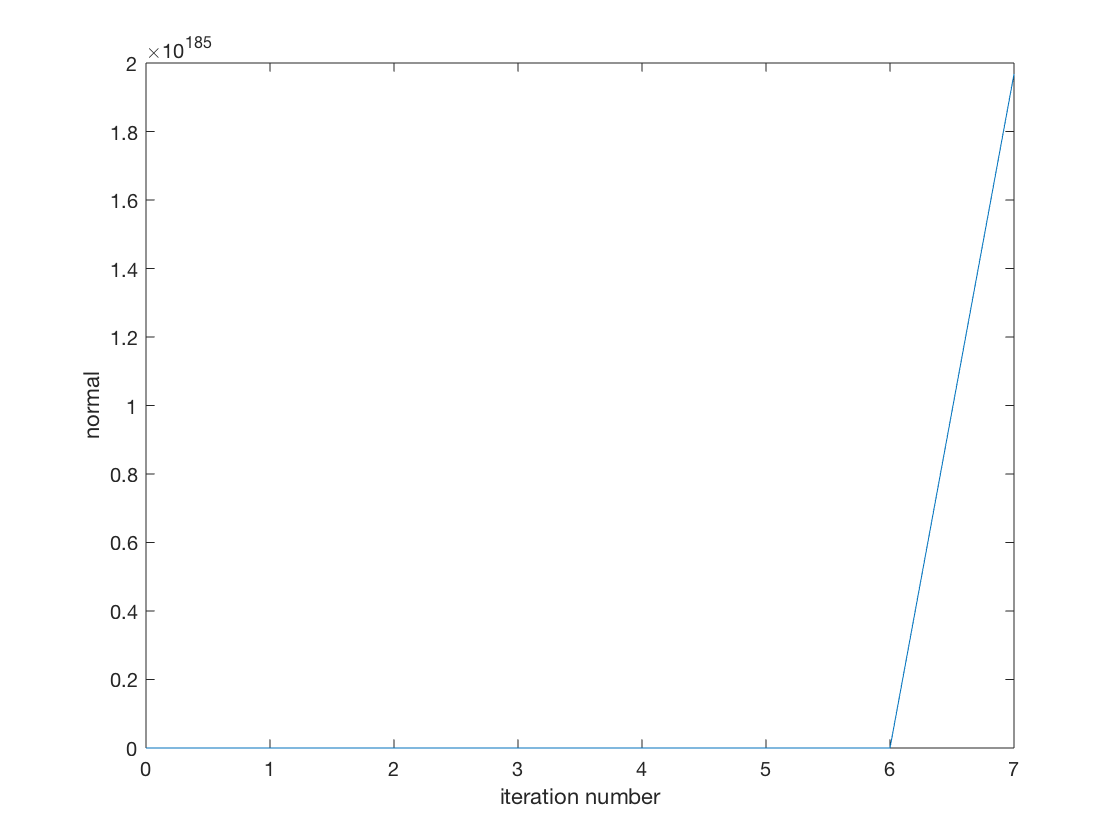

plot(fx(1,1:x),fx(2,1:x))
ylabel('normal')
xlabel('iteration number')

% from the conclusion of the plot, the proper initial guess is very important, we should always pick the most proper initial guesses.
% I can see that my graph stops when it reaches nan because my initial is -4,  the graph would jump to the high value directly. 

d) In this part re-implement** Newton-Raphson Method** from part c) to find the roots of $f\left(x\right)\;=\;\arctan \left(x\right)$.

Use $x^{\left(0\right)} =1\ldotp 40$ as initial guess.  Comment on your findings. 

Implement your code in the cell below. Did the Newton-Raphson converge to the root of $f\left(x\right)$? What can you conclude?

f = 1;
s = 1;
x = 0;
ka = 1.39;
kb = ka;
tol = 1e-5;
x1 = atan(kb);
fx = zeros(2,100);

while f >= tol && s >=tol
fx(1,x+1) = x;
df = 1/(kb^2+1);
kb = kb-x1/df;
x1 = atan(kb);
s = norm(kb-ka);
f = norm(x1);
fx(2,x+1) = s;
if x == 100
s = 1e-6;
f = 1e-6;
fprintf("Iteration over 101 times, Newton-Raphson can't converge")
end
ka = kb;
x = x+1;
end
if x < 100
finalx = ka
numberofit = x-1
end

finalx = 5.7004e-13

numberofit = 9

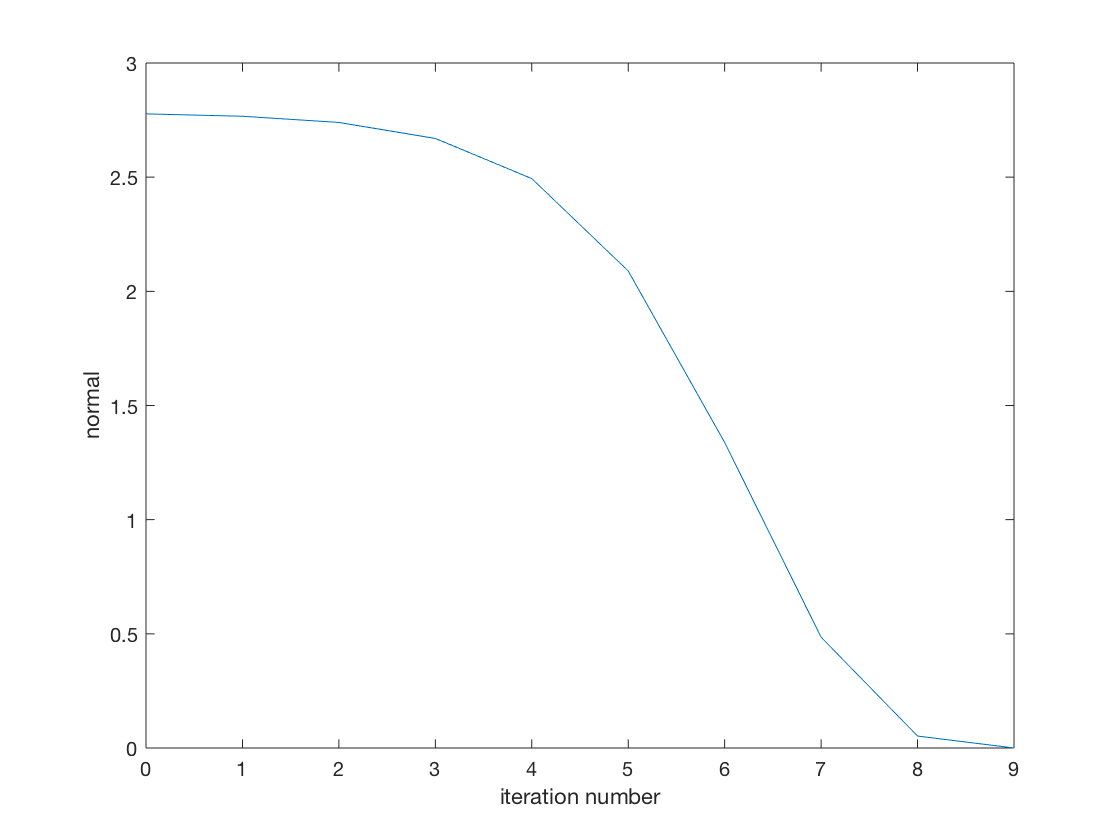

plot(fx(1,1:x),fx(2,1:x))
ylabel('normal')
xlabel('iteration number')

% the Newton-Raphson converge to the root of f(x) in the end, I can conclude that the initial value is very important.
% the lower initial guess 1.39/1.4 makes my graph moving slower and more accurate.  

Question 2:  **Nonlinear Equations for N-variables.**

 Newton-Raphson Method can be used to solve the system of nonlinear equations of N-variables, $\left\lbrack x_1 ,\;x_2 ,\;\cdots ,\;x_n \right\rbrack$shown below,


$$f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$



$$f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$
 


$$\vdots$$



$$f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$


The above equations can be written as a vector valued function as shown below,


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
\vdots \\
f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)
\end{array}\right\rbrack$$


where $\mathit{\mathbf{X}}=\left\lbrack x_1 ,x_2 ,\cdots ,x_N \right\rbrack$ is the vector containing all the variables.

Following the idea of unidimensional Newton-Rapshson, we start with an initial guess ${\mathit{\mathbf{X}}}^{\left(0\right)}$ and we use this to linearise the function $\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)$ around${\;\mathit{\mathbf{X}}}^{\left(0\right)}$ 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\;$$

$$f\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)+\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)\right)\left(\mathit{\mathbf{X}}-{\mathit{\mathbf{X}}}^{\left(0\right)} \right)$$


Setting the expresson on the left side to zero, we find the approximation of the solution vector. After $k$ iteration the approximation for the solution vector can be written as 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


where $\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$ is the vector valued fucntion evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$ and $\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$ is the jacobian evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$. The structure of the Jacobian is given by,


$$\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 } & \cdots  & \frac{\partial f_1 }{\partial x_n }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 } & \cdots  & \frac{\partial f_2 }{\partial x_n }\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial f_n }{\partial x_1 } & \frac{\partial f_n }{\partial x_2 } & \cdots  & \frac{\partial f_n }{\partial x_n }
\end{array}\right\rbrack$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

Find a solution of the following system of three nonlinear equations using Newton-Raphson method.


$$x_{1\;} x_2 -x_3^2 =1$$



$$x_{1\;} {\;x}_2 \;x_3 -x_1^2 +x_2^2 =2$$



$$e^{x_1 } -e^{x_2 } -x_3 =0$$


Note that this can be expressed as 

$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
x_{1\;} x_2 -x_3^2 -1\\
x_{1\;} {\;x}_2 \;x_3 -x_1^2 +x_2^2 -2\\
e^{x_1 } -e^{x_2 } -x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$,        where $\mathit{\mathbf{X}}={\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack }^T$

a) Write a MATLAB function named *evaluateEquations(x)*, that evaluates the above equation at a given input vector. 

Use the framework of the function provided in the Appendix. 

b) Write a MATLAB function named *evaluateJacobian()*, that evaluates the Jacobian of the above equations. 

Use the framework of the function provided in the Appendix. 

c) Implement the Newton-Raphson method, use the function named *NewtonRaphson() *to write the code for this. Use initial guess, $X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
35 & 0 & 2
\end{array}\right\rbrack }^T$. Plot the 2-Norm of difference between consecutive solutions ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2$ for each iteration. 

Xguess = [35 0 2]';
[X,iter,delta] = NewtonRaphson(Xguess,1e-5)

X =     1.6684
    1.4192
    1.1695


iter = 36

delta =          0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
  143.3750   71.7122   35.7811   17.6406    8.0595    2.5852    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9998    0.9994    0.9986    0.9965    0.9915    0.9793    0.9508    0.8873    0.7559    0.5213    0.2192    0.0315    0.0006         0         0         0         0         0         0         0         0         0         0         0         0 

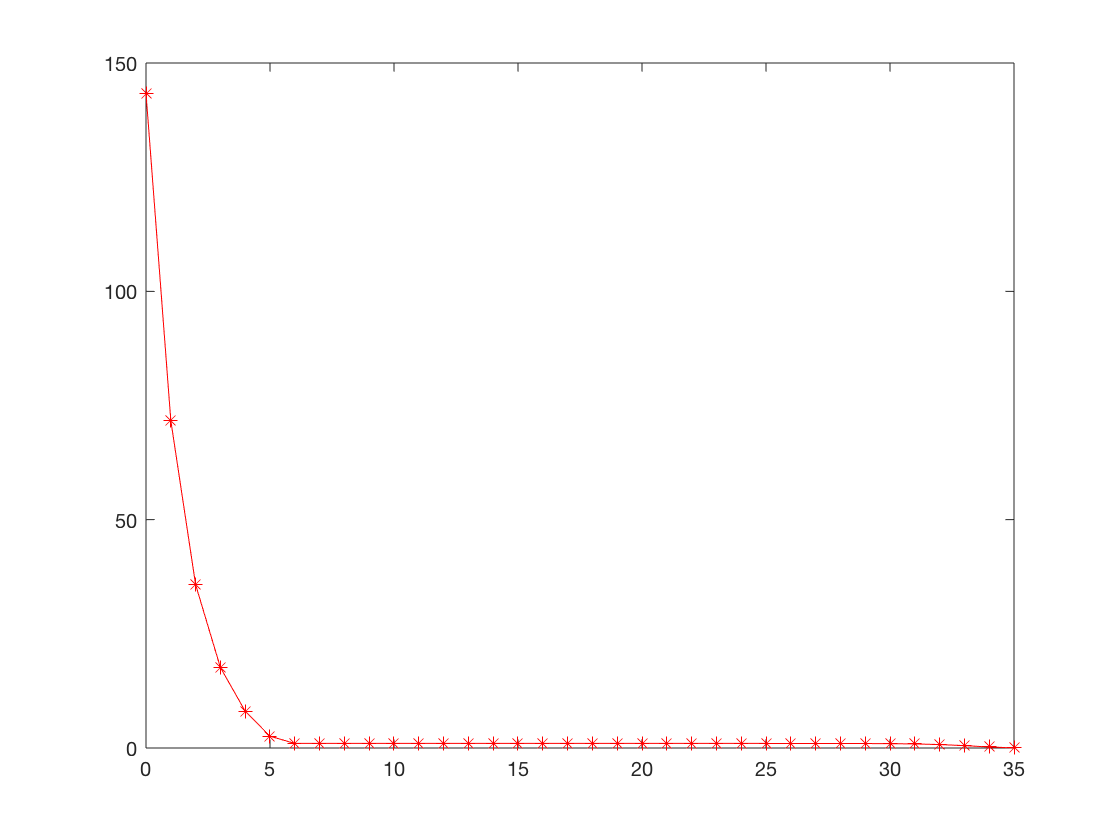

plot(delta(1,1:iter),delta(2,1:iter),'r-*')

d) Run the part c) using the intial guess  $X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
0\ldotp 15 & 0 & 0
\end{array}\right\rbrack }^T$ Explain the differences.** Why is the result  in part (c) different than the result obtained in part (d)? **

Xguess = [0.15 0 0]';
[X2,iter2,deta2] = NewtonRaphson(Xguess,1e-5)

X2 =    -0.7162
   -1.4935
    0.2640


iter2 = 20

deta2 =          0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   14.3375    8.0308    4.7487    3.3089    1.4267    1.8252    2.1498    1.0356    6.4912    8.1770   10.2587    2.0257    3.5837    1.5512    1.8813    1.3658    0.8577    0.4595    0.1130    0.0077    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

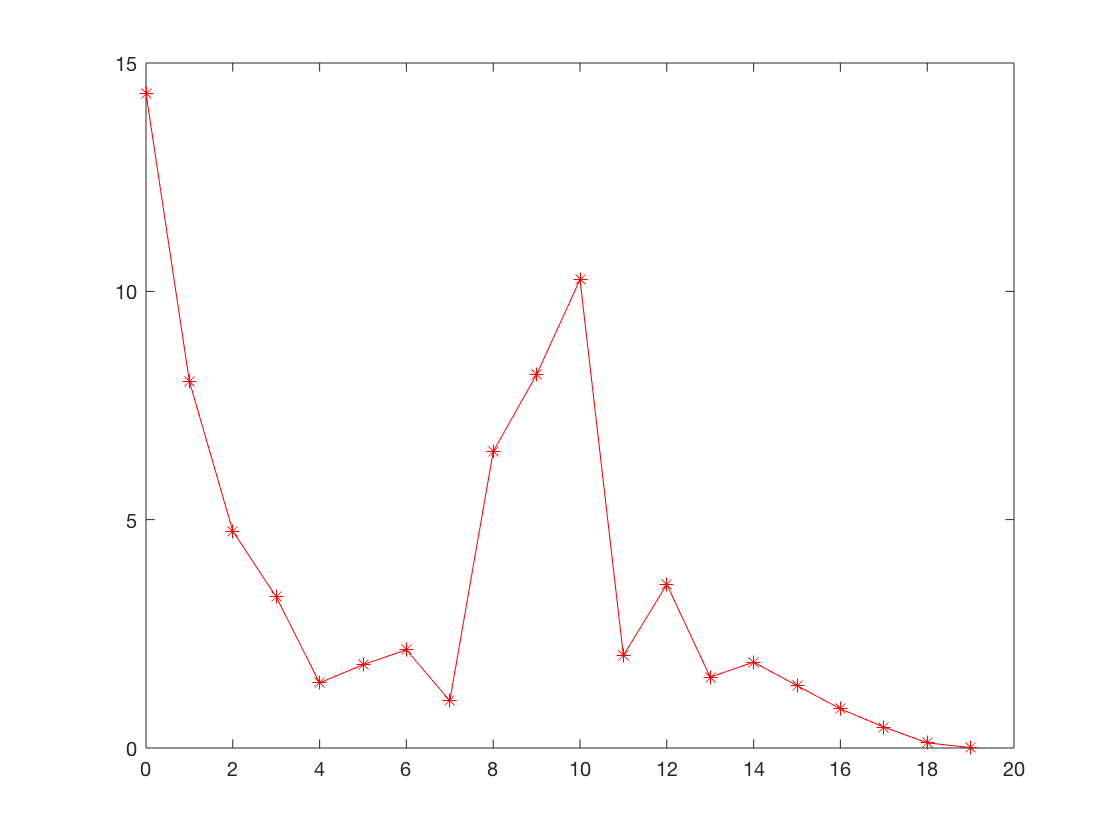

plot(deta2(1,1:iter2),deta2(2,1:iter2),'r-*')

% the reuslt in part c different than part b because they have different initial guess, 
% the function has many different roots. 

# Appendix

Question 2) a)

function f  = evaluateEquations(x)
f = [x(1)*x(2)-x(3)^2-1;x(1)*x(2)*x(3)-x(1)^2+x(2)^2-2;exp(x(1))-exp(x(2))-x(3)];
end 


Question 2) b)

function J  = evaluateJacobian(x)
syms x1 x2 x3
l = length(x);
sum = [x1 x2 x3];
J = sym('J',[3 3])';
s = [x1*x2-x3^2-1;x1*x2*x3-x1^2+x2^2;exp(x1)-exp(x2)-x3];
for i = 1:l
for j = 1:l
J(i,j) = diff(s(i),sum(j));
end
end
J = subs(J, {x1 x2 x3}, x');
end

Question 2) c)

function [Xout,iterations,delta]  = NewtonRaphson(Xguess,tolerance)
f = 1;
s = 1;
x = 0;
k1 = Xguess;
k2 = k1;
t = tolerance;
y = zeros(2,100);
x1 = evaluateEquations(k2);

while s >= t && f >=t
y(1,x+1) = x;
df = evaluateJacobian(k2);
k2 = double(k2-df\x1);
s = double(norm(k2-k1,"inf"));
x1 = evaluateEquations(k2);
f = double(norm(x1,"inf"));
y(2,x+1) = s;
if x == 100
s = 1e-6;
f = 1e-6;
fprintf("Iteration over 101 times, Newton-Raphson can't converge")
end
k1 = k2;
x = x+1;
end
if x < 100
delta = y;
Xout = k1;
iterations = x-1;
end
end
